## 0. 데이터 불러오기 및 전처리

### 0.1. 데이터 불러오기

channel object 생성 및 데이터 처리: reading_method_guide.mlx 참고

reader = channelReader();
tic 
%                                 filename,        channelColumnIdx, timeColumnIdx, startRowIdx, startColIdx, sampleRate
%reader.readMultiChannelFile("./data/1_singleunit wave.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴
reader.readMultiChannelFile("/Users/jmmoon/Documents/GitHub/neurosignal-matlab/data/1_singleunit wave.xlsx", 1,        3,             7,             4,           nan); %일단 파일을 불러옴

This file has 16 channels: 

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16



toc % 코드 실행 시간 측정. 오래 걸림.

Elapsed time is 72.386792 seconds.



%                 organoid, channel, month 
o1_ch8_m1 = reader.readSingleChannelFromFile(1, 8, 1); %8번 채널 데이터를 불러옴 

channel number = 8
sampling rate = 24414.062743Hz
starts at 0.000000, ends at 23.152517, duration = 23.152517
number of timestamps = 565248



%                   passband
o1_ch8_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
                        %thres, preTime, postTime
o1_ch8_m1.detectSpikes(5,2,2);

number of spikes found : 113


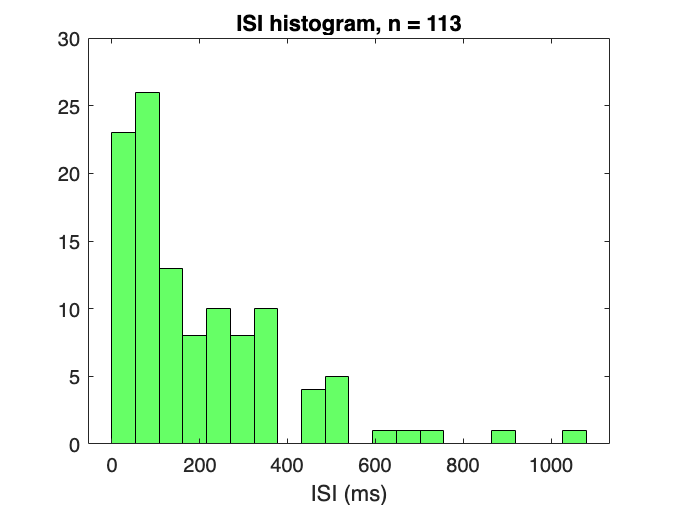

%
ISIvaluesBeforePCA = o1_ch8_m1.getISIvaluesBeforePCA(); %PCA, kmeans 전에 전체 spike 대상 ISI 계산값 가져오기
nSpikes = o1_ch8_m1.nSpikes;

figure
h1 = histogram(ISIvaluesBeforePCA, 20); % bin 개수 20개로 설정. 변경 가능
title('ISI histogram, n = ' + string(nSpikes) ); %plot 제목 
xlabel('ISI (ms)'); % plot x축 변수 이름
h1.FaceColor = "green"; %색상 지정

%
% begISI, endISI , minSpikes, minDurn, minIBI, (in milisecond)
% the order of the parameters is the same as the reference [1]
burstDetectionResult = o1_ch8_m1.detectBurstsMI(300, 301, 10, 50, 200) %[1]과 똑같은 parameter 값을 사용

phase 1 result: found 22 bursts, using parameters begISI and endISI

phase 2 result: after merging by minIBI, 22 bursts left

phase 3 result: 20 bursts were removed whose duration is less than 50 milisecond or have spikes less than 10 

burstDetectionResult = 2×6 table
    beg    end     IBI     nSpikes     durn     meanISI
    ___    ___    _____    _______    ______    _______

     9      22      NaN      14       1855.9    142.76 
    85     102    15529      18       1331.7    78.335 


%
o1_ch8_m1.getPCScores();

%
                           %clusternum, seednum
o1_ch8_m1.getKmeansClusters(3,2212323231);

number of spikes per cluster:
cluaster 1: 80 
cluaster 2: 12 
cluaster 3: 21 


#### 0.5.1. Spike sorting quality metrics

pcs_for_this_unit = o1_ch8_m1.PCScores(o1_ch8_m1.clusters == 1,:)

pcs_for_this_unit =    -0.8097   -3.3679
   -1.5357    2.5456
   -0.9419    2.3879
   -2.9763   -0.2595
   -3.8041   -1.7028
    1.9645    1.0484
    0.5326    1.9676
    1.3181   -1.4288
    0.0389   -4.8005
   -0.8189    4.3409


pcs_for_other_units = o1_ch8_m1.PCScores(o1_ch8_m1.clusters ~= 1, :)

pcs_for_other_units =    11.4243    0.5691
   11.8056    3.2905
  -12.9160    2.6309
    8.8565    1.4993
   -3.0277    5.8462
   11.6134    0.5159
   -1.6342    6.8181
    8.0750    0.5420
  -11.3452   10.1180
    9.8278    0.4322


n_this_unit = size(pcs_for_this_unit, 1)

n_this_unit = 80

n = min( size(pcs_for_this_unit, 1), size(pcs_for_other_units, 1) ) % number of spikes

n = 33

mahalanobis_other = sort(mahal(pcs_for_other_units, pcs_for_this_unit))

mahalanobis_other =     3.9361
    5.2036
    5.7096
    6.4955
    8.8300
   21.0506
   22.3583
   27.6805
   30.2454
   30.6639


dof = size(pcs_for_this_unit, 2) % number of features

dof = 2

isolation_distance = power(mahalanobis_other(n),2)

isolation_distance = 3.2995e+03

f

isolation_distance = power(mahalanobis_other(n),2)

isolation_distance = 3.2995e+03

l_ratio = sum(chi2cdf(power(mahalanobis_other,2),dof,'upper')) / n_this_unit

l_ratio = 5.4212e-06